## Семинар 13. Сингулярное разложение матрицы эксперимента и спектральное разложении матрицы ковариции

#### Немного  теорвера и матстата

У нас есть случаная переменная, которая может принимать некоторый (дискретный) набор возможных значений:


$$x \sim x_1 \dots x_N$$
 

Вероятность переменной иметь некоторое определенноей значение из этого дискретного набора характеризуется набором вероятностей:

$P \sim p_1 \dots p_N$, $\Sigma_ip_i=1$

Для некоторой случайно переменной, которая получается из некоторого распределения $P$, математическое ожидание будет:


$$m=\mathbb{E}(x\sim P)=\Sigma_ip_ix_i$$


Среднее значение результатов набора из $M$ испытаний:

$\mu=\frac{\Sigma_{j=1}^Mx_j} {M}$ - применяется для экспериментальной оценки мат. ожидания.

Разброс данных характеризуется вариацией:


$$\nu=\mathbb{E}[(x-m)^2]=\Sigma_ip_i(x_i-m)^2$$


Для экспериментальной оценки вариации:


$$\sigma= \frac {\Sigma_{j=1}^M(x_j-\mu)^2} {M-1}$$


Если случаная величина характеризуется векторов, то есть состояний несколько, например, $[\matrix {x \cr y}]$, каждая из компонент идет из своего распределения, то :


$$\sigma_x= \frac {\Sigma_{j=1}^M(x_j-\mu_x)^2} {M-1}, \sigma_y= \frac {\Sigma_{j=1}^M(y_j-\mu_y)^2} {M-1}$$


Если есть две переменных, то появляется ковариация, которая характеризуется совместной вероятностью события с вектором состояний $[\matrix {x_i \cr y_j}]$.


$$\nu=\mathbb{E}[(x-\mathbb{E}[x])(y-\mathbb{E}[y])]=\Sigma_{ik}p_{ik}(x_i-m_x)(y_k-m_y)$$


$p_{ik}$ - совместная вероятность 

#### Матрица ковариации:

$\vec{X_1}...\vec{X_m}...\vec{X_M}$ - вектора результатов испытания (определения $N$ свойств)  "образца" размером $N \times 1
$ каждый (вектора состояния некоторого случайного процесса). 

$M$ - число испытаний, $N$ - число свойств ($N<M$)

$\vec{\mu} = \mu_1 ... \mu_n ... \mu_N$ - средние  значения по всем испытаниям для каждого из свойств: $\mu_n=\frac{\sum_{i=1}^{M} x_{ni}} {M}$

clearvars
x1 = sym("x1",[2 1])
x2 = sym("x2",[2 1])
x3 = sym("x3",[2 1])
mu = sym("mu",[2,1])
% три измерения двух свойств N = 2, M = 3

Матрица матрица испытаний $[N\times M]$:

$A = [\vec{X_1}-\vec{\mu},{...},\vec{X_m}-\vec{\mu},{...},\vec{X_N}-\vec{\mu}]$ - каждый столбец - вектор результатов измерений (вектор состояния), смещенный на среднее значение ($[{...}]$ - операция конкатенации)

A = [x1-mu,x2-mu,x3-mu]

Экспериментальная оценка матрицы ковариации (симметричная матрица размером $N \times N$):

$C =\frac {A A^T} {(M-1)}$                                                                                                                                 (3)

C = A*transpose(A)*sym("1/2")

Диагональные элементы матрицы $C_{nn}$- коэффициенты вариации ($n=1{...}N$),  для  $n$ - го  свойства : $C_{nn}=\frac {\sum_{i=1}^{M}(x_{ni}-\mu_n)^2}{M-1}$  

Если из диагональных элементов извлечь корень и поделить на количество экспериментов $L$, то получим стандартное отклонение среднего арифметического.

Элементы матрицы $C$, стоящие вне диагонали, -  коэффициенты ковариации   $n$ - го  и $m$ - го свойств: $C_{nk}=\frac {\sum_{i=1}^{M}[ (x_{ni}-\mu_n)(x_{ki}-\mu_k)]} {M-1}$ ($n,k=1{...}N , n \not = k$) 

Эти формулы понятнее, если посмотреть не на матрицу $A$, на транспонированную матрицу $B=A^T$, в матрице $B$, каждый столбец ($\vec{b}_n$), размером $[M \times 1]$  будет соответствовать какому-то свойству, измеренному $M$ раз. Тогда вектор средних $\vec{\mu}$ - это вектор средних значений по каждому из столбцов. 

То есть, хотя табличка данных одна и та же в зависимости от того как на нее смотреть ее интерпретация различна: 

матрица $A$ - это набор испытаний, в каждом из которых был определен некоторый набор свойств, 

матрица $B=A^T$ - это набор свойств, для каждого из которых было выполнено некоторое число испытаний.

B = transpose(A)
b1 = B(:,1)
b2 = B(:,2)

 В соответствии с (3), матрица ковариации через матрицу свойств $B$ выражается в виде: 

$C = A A^T/(M-1)= B^T  B/(M-1)$                                                                                                                               (4)

То есть, диагональные элементы матрицы ковариации (вариация) $C_{nn}=\frac {\vec{b}_n^T  \vec{b}_n} {M-1}$ - это просто скалярное произведение столбца матрицы $B$ самого на себя, а элементы, стоящие вне диагонали - это скалярные произведения различных столбцов матрицы $B$:  $C_{nk}=\frac {\vec{b}_n^T\vec{b}_k} {M-1}$ скалярное произведение двух векторов характеризует то насколько один вектор "отстоит" от другого, по сути это проекция одного вектора на другой. Если оба вектора единичные по амплитуде, то это косинус угла между ними. Если скалярное произведение равно нулю, то вектора сонаправлены, то есть максимально "зависимы".

C_b = transpose(B)*B

#### Спектральное разложение матрицы ковариации <=> сингулярное разложение матрицы измерений:

Пусть матрица измерений $A$ имеет следующее сингулярное разложение:


$$A=U \Sigma V^T$$
 

 Тогда матрица ковариации может быть представлена в виде:

$C = A A^T = (U \Sigma  V^T) (U \Sigma  V^T) ^T =  (U \Sigma V^T) (V  \Sigma U^T)  =  U \Sigma^2  U^T$                                                                                                                     (5)


$$C = U \Sigma^2  U^T=U \Sigma^2  U^{-1}$$
  

$C  =P  \Lambda  P^{-1}$ - спектральное разложение матрицы ковариации 

Столбцы матрицы собственных векторов не ортонормированы, однако, для симметричной положительно определенной матрицы $C$, которой является матрица ковариации, они ортогональны, то есть: $P^{-1}=P^T$, таким образом, левые сингулярные вектора матрицы испытаний есть нормированные собственные вектора матрицы ковариации, а собственные значения - квадраты сингулярных значений.

#### Пример корреляции при бросании двух монеток.

Испытание - однократное бросание двух монеток (вектор состояния системы из двух монеток -1/2 - решка, +1/2 - орел). 

Свойство - состояние одной монетки.

Если монетки некоррелированы, то в каждом испытании состояние каждой из монет не зависит от состояния другой.

Монетки максимально коррелированы, когда одна приклеена к другой.:

clearvars
points_number = 500; % число бросаний
% монетки независимы друг от друга
first_coin = (rand(points_number,1)>=0.5) - 0.5; % +-1/2 орел/решка, среднее - ноль
second_coin = (rand(points_number,1)>=0.5) -0.5;
disp("Матрица испытаний для независимых монет: ")
A = transpose([first_coin-mean(first_coin),second_coin-mean(second_coin)]) % матрица испытаний
disp("Матрица свойств: ")
B = A' % матрица свойтсв
ncorrelated_coins_covariance_matrix = transpose([first_coin,second_coin])*[first_coin,second_coin]/(points_number-1);
disp("Монетки бросаются независимо друг от друга:")
disp(ncorrelated_coins_covariance_matrix)
disp("Матрица ковариации близка к диагональной - максимально несингулярна, колонки полностью независимы")
% монетки приклеены друг к другу одноименными концами
first_coin_dependent = (rand(points_number,1)>=0.5) - 0.5;

$$x1 = \left(\begin{array}{c} x_{11}\\ x_{12} \end{array}\right)$$

first_coin_dependent = first_coin_dependent-mean(first_coin_dependent);

$$x2 = \left(\begin{array}{c} x_{21}\\ x_{22} \end{array}\right)$$

disp("Матрица испытаний для склееных монет: ")

$$x3 = \left(\begin{array}{c} x_{31}\\ x_{32} \end{array}\right)$$

Acor=transpose([first_coin_dependent,first_coin_dependent]) % матрица испытаний

$$mu = \left(\begin{array}{c} \mu_{1}\\ \mu_{2} \end{array}\right)$$


correlated_coins_covariance_matrix = transpose([first_coin_dependent,first_coin_dependent])*[first_coin_dependent,first_coin_dependent]/(points_number-1);
disp("Монетки склеены одноименными концами, матрица ковариации:")
disp(correlated_coins_covariance_matrix)


$$A = \left(\begin{array}{ccc} x_{11}-\mu_{1} & x_{21}-\mu_{1} & x_{31}-\mu_{1}\\ x_{12}-\mu_{2} & x_{22}-\mu_{2} & x_{32}-\mu_{2} \end{array}\right)$$

disp("Матрица ковариации сингулярна, так как колонки одинаковы, то есть линейно зависимы")


disp("Сингулярное разложение матрицы ковариации для независимых монеток")

$$C = \begin{array}{l} \left(\begin{array}{cc} \frac{{\left(\mu_{1}-x_{11}\right)}^{2}}{2}+\frac{{\left(\mu_{1}-x_{21}\right)}^{2}}{2}+\frac{{\left(\mu_{1}-x_{31}\right)}^{2}}{2} & \sigma_{1}\\ \sigma_{1} & \frac{{\left(\mu_{2}-x_{12}\right)}^{2}}{2}+\frac{{\left(\mu_{2}-x_{22}\right)}^{2}}{2}+\frac{{\left(\mu_{2}-x_{32}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\left(\mu_{1}-x_{11}\right)\,\left(\mu_{2}-x_{12}\right)}{2}+\frac{\left(\mu_{1}-x_{21}\right)\,\left(\mu_{2}-x_{22}\right)}{2}+\frac{\left(\mu_{1}-x_{31}\right)\,\left(\mu_{2}-x_{32}\right)}{2} \end{array}$$

[U,S] = svd(A)
disp("Спектральное разложение матрицы ковариации для независимых монеток")
[Q,L] = eig(A*A')
disp("Сингулярное разложение матрицы ковариации для склееных монеток")
[U,S] = svd(Acor)
disp("Спектральное разложение матрицы ковариации для склееных монеток")
[Q,L] = eig(Acor*Acor')

## Примеры использования 

### Пример использования  - детерминированные данные: колебание грузика на пружине и два датчика

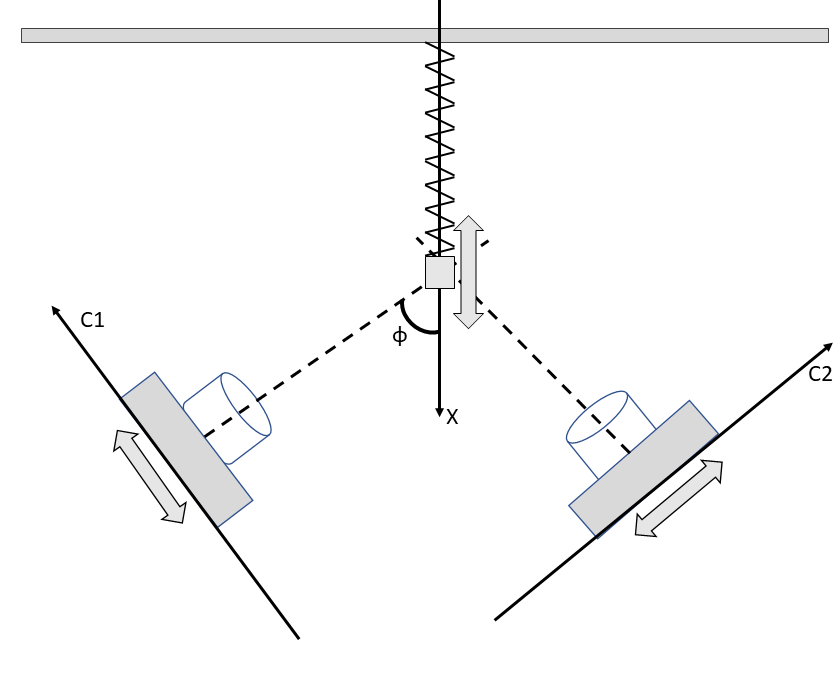

clearvars
t = linspace(-pi,pi,100) % фаза движения 

$$B = \left(\begin{array}{cc} x_{11}-\mu_{1} & x_{12}-\mu_{2}\\ x_{21}-\mu_{1} & x_{22}-\mu_{2}\\ x_{31}-\mu_{1} & x_{32}-\mu_{2} \end{array}\right)$$

X = cos(t) % закон движения грузика на пружине

$$b1 = \left(\begin{array}{c} x_{11}-\mu_{1}\\ x_{21}-\mu_{1}\\ x_{31}-\mu_{1} \end{array}\right)$$

phi = 30; % угол ориентации камер относительно оси колебания грузика

$$b2 = \left(\begin{array}{c} x_{12}-\mu_{2}\\ x_{22}-\mu_{2}\\ x_{32}-\mu_{2} \end{array}\right)$$

c1 = X*cosd(phi); % показания камеры 1
c2=X*sind(phi); % показания камеры 2
A=[c1;c2] % матрица эксперимента 
scatter(c2,c1);
xlabel("Показания первого датчика")

$$C\_b = \begin{array}{l} \left(\begin{array}{cc} {\left(\mu_{1}-x_{11}\right)}^{2}+{\left(\mu_{1}-x_{21}\right)}^{2}+{\left(\mu_{1}-x_{31}\right)}^{2} & \sigma_{1}\\ \sigma_{1} & {\left(\mu_{2}-x_{12}\right)}^{2}+{\left(\mu_{2}-x_{22}\right)}^{2}+{\left(\mu_{2}-x_{32}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(\mu_{1}-x_{11}\right)\,\left(\mu_{2}-x_{12}\right)+\left(\mu_{1}-x_{21}\right)\,\left(\mu_{2}-x_{22}\right)+\left(\mu_{1}-x_{31}\right)\,\left(\mu_{2}-x_{32}\right) \end{array}$$

ylabel("Показания второго датчика")
[V,S,U] = svd(A) % считаем сингулярное разложение
% спектр сингулярных значений состоит из одного значения, это значит, что
% нам достаточно одного датчика!
cosd(phi) % косинус угла ориентации датчиков
sind(phi) % синус угла ориентации датчиков
V2 = [cosd(phi) sind(phi);...
     sind(phi) -cosd(phi)] % матрица вращения на угол фи в двумерном пространстве
% Таким образом, V - матрица поворота
rad2deg(subspace(A,[1;0])) % угол между подпространством матрицы измерений единичным вектором (вектор X рисунке), так как матрица 
% A - сингулярна (измерения полностью коррелированы), ее подпространство
% состоит из одного вектора, поэтому углом между поодпространством ее
% столбцов и вектором будет угол фи
disp("Матрица ковариации:")
C = A*A'/(numel(t)-1)

#### Пример использования: "случаные" данные

#### Генерация исходных данных по трем свойствам (два из них - коррелированы)

clearvars
rand_fun = "randn"; % выбираем статистику из которой набираются "экспериментальные точки" randn - Гауссово распределение, rand - равномерное распределение от 0 до 1
rand_fun_handle = str2func(rand_fun); % форма распределения
points_number = 90; % число экспериментальных точек
X = 60 + rand_fun_handle(points_number,1); % генерим массив случайных точек (результаты измерения первого параметра)
Y = 1.26+ 0.1*rand_fun_handle(points_number,1); % генерим массив случайных точек (результаты измерения второго параметра) полностью случайны, не зависят от X

Матрица испытаний для независимых монет: 


alfa_cor =0.75;

A =    -0.5240   -0.5240    0.4760    0.4760    0.4760    0.4760   -0.5240    0.4760   -0.5240    0.4760    0.4760    0.4760   -0.5240   -0.5240    0.4760   -0.5240   -0.5240   -0.5240   -0.5240    0.4760   -0.5240   -0.5240   -0.5240    0.4760   -0.5240    0.4760   -0.5240    0.4760    0.4760    0.4760    0.4760   -0.5240   -0.5240   -0.5240    0.4760   -0.5240   -0.5240   -0.5240   -0.5240    0.4760   -0.5240    0.4760    0.4760   -0.5240   -0.5240    0.4760    0.4760   -0.5240   -0.5240    0.4760
    0.5180   -0.4820    0.5180   -0.4820   -0.4820   -0.4820   -0.4820   -0.4820   -0.4820   -0.4820    0.5180   -0.4820   -0.4820   -0.4820   -0.4820   -0.4820   -0.4820    0.5180    0.5180   -0.4820   -0.4820   -0.4820   -0.4820    0.5180    0.5180    0.5180   -0.4820    0.5180   -0.4820    0.5180    0.5180   -0.4820    0.5180   -0.4820    0.5180    0.5180   -0.4820   -0.4820   -0.4820    0.5180    0.5180    0.5180   -0.4820    0.5180   -0.4820    0.5180   -0.4820    0.5180   -0.4820    0

Ycor = 3 + (alfa_cor*X + (1-alfa_cor)*rand_fun_handle(points_number,1));% Ycor - коррелирует с X

Матрица свойств: 


disp("Матрица свойств:")

B =    -0.5240    0.5180
   -0.5240   -0.4820
    0.4760    0.5180
    0.4760   -0.4820
    0.4760   -0.4820
    0.4760   -0.4820
   -0.5240   -0.4820
    0.4760   -0.4820
   -0.5240   -0.4820
    0.4760   -0.4820


t1 = table(X,Y,Ycor,'VariableNames',["Прочность" "Теплопроводность" "Удельная поверхность"]);
disp(t1)

Монетки бросаются независимо друг от друга:


disp("Матрица испытаний:")

    0.2505    0.0030
    0.0030    0.2505



disp([X';Y';Ycor'])

Матрица ковариации близка к диагональной - максимально несингулярна, колонки полностью независимы


% СЧИТАЕМ СРЕДНИЕ И НОРМИРУЕМ 

Xn = (X-mean(X)); % смещаем среднее для первого свойства
Yn = (Y - mean(Y));% смещаем среднее для второго свойсва

Матрица испытаний для склееных монет: 


Ycorn = ((Ycor - mean(Ycor))); % нормированные данные

Acor =     0.4940   -0.5060    0.4940   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940   -0.5060   -0.5060    0.4940   -0.5060    0.4940    0.4940    0.4940    0.4940    0.4940   -0.5060   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940   -0.5060    0.4940   -0.5060    0.4940   -0.5060    0.4940    0.4940   -0.5060   -0.5060    0.4940   -0.5060   -0.5060   -0.5060    0.4940   -0.5060    0.4940    0.4940   -0.5060   -0.5060
    0.4940   -0.5060    0.4940   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940   -0.5060   -0.5060    0.4940   -0.5060    0.4940    0.4940    0.4940    0.4940    0.4940   -0.5060   -0.5060    0.4940    0.4940    0.4940   -0.5060    0.4940    0.4940   -0.5060    0.4940   -0.5060    0.4940   -0.5060    0.4940    0.4940   -0.5060   -0.5060    0.4940   -0.5060   -0.5060   -0.5060    0.4940   -0.5060    0.4940    0.4940   -0.5060  


% вначале рассмотрим матрицы 2х2
A2 = transpose([Xn,Yn]); % матрица испытаний для некоррелированных параметров (два параметра)

Монетки склеены одноименными концами, матрица ковариации:


A2cor = transpose([Xn,Ycorn]); % матрица испытаний для коррелированных параметров (два параметра)

    0.2505    0.2505
    0.2505    0.2505



A3 = transpose([Xn,Yn,Ycorn]); % матрица испытаний для всех трех свойств
covMATuncor = A2*transpose(A2)/(points_number-1); % матрица ковариации для некоррелированных данных

Матрица ковариации сингулярна, так как колонки одинаковы, то есть линейно зависимы


covMATcor =  A2cor*transpose(A2cor)/(points_number-1);% матрица ковариации для коррелированных данных
covMAT3 = A3*transpose(A3)/(points_number-1);
disp("Матрица ковариации независимых друг от друга данных:")

Сингулярное разложение матрицы ковариации для независимых монеток


disp(covMATuncor)

U =     0.6940   -0.7200
    0.7200    0.6940


S =    11.2469         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   11.0931         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

disp("Матрица ковариации взаимосвязанных данных Y="+alfa_cor+"*X +"+(1-alfa_cor)+"*rand")

Спектральное разложение матрицы ковариации для независимых монеток


disp(covMATcor)

Q =    -0.7200    0.6940
    0.6940    0.7200


L =   123.0578         0
         0  126.4922


disp("Матрица ковариации для трех параметров {X=rand,rand,Y="+alfa_cor+"*X +"+(1-alfa_cor)+"*rand}")

Сингулярное разложение матрицы ковариации для склееных монеток


disp(covMAT3)

U =    -0.7071    0.7071
   -0.7071   -0.7071


S =    15.8102         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Спектральное разложение матрицы ковариации для склееных монеток


scatter(t1.("Прочность"),t1.("Теплопроводность"));

Q =    -0.7071    0.7071
    0.7071    0.7071


L =          0         0
         0  249.9640


xlabel(t1.Properties.VariableNames{1});
ylabel(t1.Properties.VariableNames{2});
title("Независимые параметры")
grid on 
scatter(t1.("Прочность"),t1.("Удельная поверхность"));
xlabel(t1.Properties.VariableNames{1});

t =    -3.1416   -3.0781   -3.0147   -2.9512   -2.8877   -2.8243   -2.7608   -2.6973   -2.6339   -2.5704   -2.5069   -2.4435   -2.3800   -2.3165   -2.2531   -2.1896   -2.1261   -2.0627   -1.9992   -1.9357   -1.8723   -1.8088   -1.7453   -1.6819   -1.6184   -1.5549   -1.4915   -1.4280   -1.3645   -1.3011   -1.2376   -1.1741   -1.1107   -1.0472   -0.9837   -0.9203   -0.8568   -0.7933   -0.7299   -0.6664   -0.6029   -0.5395   -0.4760   -0.4125   -0.3491   -0.2856   -0.2221   -0.1587   -0.0952   -0.0317


ylabel(t1.Properties.VariableNames{3});

X =    -1.0000   -0.9980   -0.9920   -0.9819   -0.9679   -0.9501   -0.9284   -0.9029   -0.8738   -0.8413   -0.8053   -0.7660   -0.7237   -0.6785   -0.6306   -0.5801   -0.5272   -0.4723   -0.4154   -0.3569   -0.2969   -0.2358   -0.1736   -0.1108   -0.0476    0.0159    0.0792    0.1423    0.2048    0.2665    0.3271    0.3863    0.4441    0.5000    0.5539    0.6056    0.6549    0.7015    0.7453    0.7861    0.8237    0.8580    0.8888    0.9161    0.9397    0.9595    0.9754    0.9874    0.9955    0.9995


title("Взаимосвязанные параметры")
grid on 

Собственные значения и собственные вектора матрицы ковариации:

[Q,L] = eig(covMATcor,'vector')
ax = draw_vector([],"Scattered data","","point",A2cor(1,:),A2cor(2,:));

A =    -0.8660   -0.8643   -0.8591   -0.8504   -0.8383   -0.8228   -0.8040   -0.7820   -0.7568   -0.7285   -0.6974   -0.6634   -0.6268   -0.5876   -0.5461   -0.5023   -0.4566   -0.4090   -0.3598   -0.3091   -0.2571   -0.2042   -0.1504   -0.0960   -0.0412    0.0137    0.0686    0.1232    0.1774    0.2308    0.2832    0.3346    0.3846    0.4330    0.4797    0.5245    0.5671    0.6075    0.6454    0.6807    0.7133    0.7430    0.7698    0.7934    0.8138    0.8309    0.8447    0.8551    0.8621    0.8656
   -0.5000   -0.4990   -0.4960   -0.4910   -0.4840   -0.4750   -0.4642   -0.4515   -0.4369   -0.4206   -0.4026   -0.3830   -0.3619   -0.3393   -0.3153   -0.2900   -0.2636   -0.2361   -0.2077   -0.1784   -0.1485   -0.1179   -0.0868   -0.0554   -0.0238    0.0079    0.0396    0.0712    0.1024    0.1332    0.1635    0.1932    0.2220    0.2500    0.2770    0.3028    0.3274    0.3507    0.3726    0.3930    0.4118    0.4290    0.4444    0.4581    0.4698    0.4797    0.4877    0.4937    0.4977    0

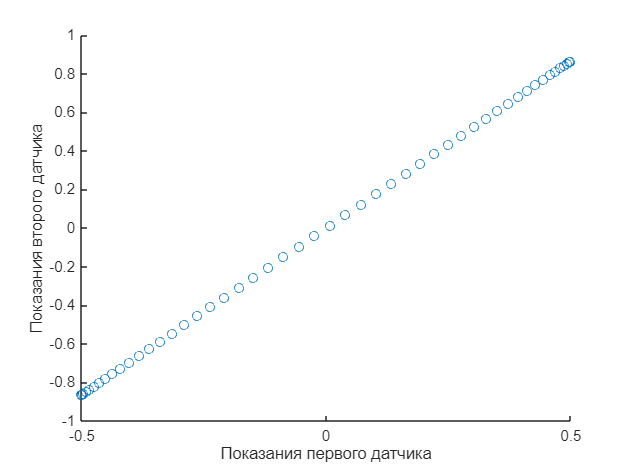

draw_vector(ax,"Собственные вектора матрицы ковариации","","vector",Q(:,1),Q(:,2))
[U,S,V] = svd(A2cor) % SVD разложение
I = ones(size(A2cor,2),1);

% если данные линейно коррелированы, почему бы не попробовать зафитить их

V =     0.8660    0.5000
    0.5000   -0.8660


S =     7.1063         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

U =    -0.1407    0.9839    0.0059    0.0197   -0.0036   -0.0173   -0.0002   -0.0182    0.0058   -0.0132    0.0203    0.0126   -0.0279   -0.0171   -0.0134   -0.0033    0.0199    0.0074    0.0013    0.0003    0.0010   -0.0052   -0.0017   -0.0008   -0.0002   -0.0003    0.0012    0.0007    0.0029    0.0050    0.0067   -0.0020   -0.0010    0.0129   -0.0118    0.0136   -0.0089   -0.0182    0.0060   -0.0007    0.0088    0.0122   -0.0155   -0.0151   -0.0118   -0.0006   -0.0014    0.0130    0.0180    0.0064
   -0.1404   -0.0174   -0.1466   -0.1575   -0.1347   -0.1200   -0.1321   -0.1124   -0.1297   -0.1081   -0.1328   -0.1203   -0.0783   -0.0815   -0.0779   -0.0797   -0.0928   -0.0739   -0.0604   -0.0512   -0.0432   -0.0290   -0.0232   -0.0151   -0.0066    0.0025    0.0102    0.0196    0.0266    0.0335    0.0407    0.0568    0.0642    0.0598    0.0894    0.0742    0.1012    0.1162    0.1009    0.1127    0.1096    0.1114    0.1405    0.1440    0.1444    0.1373    0.1402    0.1291    0.1259    0

% полиномом первой степени 
% A2cor(2,:) = lsqr_fit(1) + lsqr_fit(2)*A2cor(1,:)
vandermonde_matrix = [I A2cor(1,:)'] % матрица Вадермонда (что это?)

ans = 0.8660

lsqr_fit = atan(vandermonde_matrix\A2cor(2,:)') % решаем задачу метода наименьших квадратов (

ans = 0.5000

a_lsqrt = [cos(lsqr_fit(2));sin(lsqr_fit(2))]
draw_vector(ax,"Собственные вектора матрицы ковариации и сингулярные вектора матрицы испытаний",["u1" "u2"],"vector",U(:,1),U(:,2)*S(2,2)/S(1,1),a_lsqrt)

V2 =     0.8660    0.5000
    0.5000   -0.8660


xlim(ax,[-3,3])
ylim(ax,[-3,3])

ans = 30.0000

legend(ax,["data" "1-й собственный вектор матрицы ковариации" ...
    "2-й собственный вектор матрицы ковариации" "u1*s1" "u2*s2/s1" "фиттинг полиномом первой степени "])
% transpose(Q)*U
disp("Матрица сингулярных значений матрицы испытаний (в квадрате и нормированы на (1-N)):")

Матрица ковариации:


(S.^2)/(points_number-1)

C =     0.3826    0.2209
    0.2209    0.1275


disp(" Матрица собственных значений матрицы ковариации : ")
diag(eig(covMATcor))

Таким образом, левые сингулярные вектора дают направление векторов вдоль главных осей эллипса, первая главная ось соотвествует направлению, на которое сумма проекций максимальна.

Проекция столбцов матрицы $A$ на вектор $\vec{u_1}$:


$$\vec{u}_1^TA=\vec{u}_1^TU  \Sigma V^T = \vec{u}_1^T\sum_{i=1}^m [\sigma_i \vec{u}_i  \vec{v}_i^T]=  \sigma_1  \vec{v}_1^T$$


Амплитуда суммы проекций столбцов матрицы это длина этого вектора:


$$||\vec{u}_1^TA||= || \sigma_1  \vec{v}_1^T||=\sigma_1$$


Направление первого левого сингулярного вектора показывает вектор, сумма проекций векторов состояния (столбцы матрицы измерений) на который максимальна!

Разница между методом наименьших квадратов и сингулярным разложением показана на рисунке: 

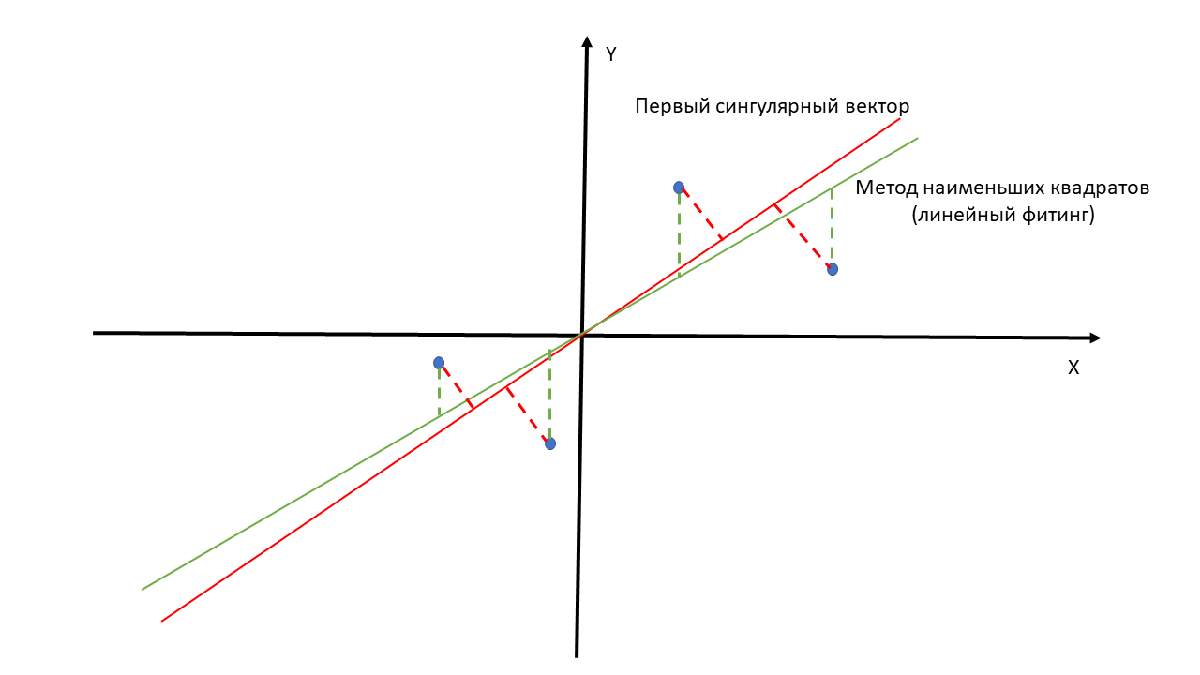

Линейная алгебра  построена так, чтобы она без проблемы экстраполировалась на пространства б**о**льшей размерности.

Три ... 

covMAT3
%ax2 = draw_vector([],"Scattered data","","point",A3(1,:),A3(2,:),A3(3,:));
[U,S,V] = svd(A3)
U(:,3)'*U(:,2)

ax2 =draw_vector([],"Scattered data","","vector",U(:,1),U(:,2),U(:,3));
draw_vector(ax2,"Scattered data","","point",A3(1,:),A3(2,:),A3(3,:));
xlim(ax2,[-3,3]);
ylim(ax2,[-3,3]);
legend(ax2,["data" "u1*s1" "u2*s2/s1" "u3*s3/s1"]);

Матрица свойств:


Пять...

clearvars -except points_number rand_fun_handle alfa_cor
X1 = randn(points_number,1);

    Прочность    Теплопроводность    Удельная поверхность
    _________    ________________    ____________________

     58.356           1.2349                46.696       
      60.48           1.5433                48.401       
     59.324           1.3219                48.062       
     60.844           1.2112                48.625       
     60.061           1.0559                 47.72       
      58.85           1.2157                46.858       
     59.683           1.4396                48.475       
     59.969           1.2386                47.883       
     58.798           1.2389                47.181       
     61.537          0.97752                49.155       
      60.71          0.98332                48.459       
     59.591           1.1642                 47.84       
     59.772           1.3748                47.786       
     60.166           1.036

X2 = randn(points_number,1);

Матрица испытаний:


X3 = randn(points_number,1);

   58.3560   60.4796   59.3239   60.8438   60.0607   58.8500   59.6832   59.9688   58.7983   61.5371   60.7104   59.5911   59.7723   60.1658   58.9252   59.6688   61.9563   61.0685   59.5776   59.0559   60.5254   61.2204   58.8184   58.8232   58.9749   59.8555   60.9380   61.1092   58.8037   60.0250   58.6146   59.9123   59.6421   60.1837   59.7155   60.8320   59.6848   59.6679   60.0668   60.3499   60.5073   58.6619   58.9459   60.2389   59.9013   59.0397   59.2344   60.2500   61.0855   59.1938   60.7409   59.0108   60.6160   57.2930   59.9814   61.7522   60.2108   59.6402   59.0070   60.8170   59.8611   59.6252   60.4336   60.3943   61.4818   59.9462   60.0757   60.7580   58.9063   58.7474   60.3561   60.0422   62.2246   59.1790   60.3010   58.6899   60.6131   59.0169   58.9020   61.5842   61.1174   60.2443   60.2655   61.6562   59.7552   59.3865   59.1130   59.7452   58.3426   59.3813
    1.2349    1.5433    1.3219    1.2112    1.0559    1.2157    1.4396    1.2386    1.2389    0.977

alfas1 = [0.01,0.01,0.07];
alfas2 = [0,0,0.08];
alfas2 = alfas2/sum(alfas2);alfas1 = alfas1/sum(alfas1);

X4 = (1-alfa_cor)*rand_fun_handle(points_number,1) + alfa_cor*sum([X1,X2,X3].*alfas1,2);
X5 = (1-alfa_cor)*rand_fun_handle(points_number,1) + alfa_cor*sum([X1,X2,X3].*alfas2,2);

C = transpose([X1,X2,X3,X4,X5])*[X1,X2,X3,X4,X5]/(points_number-1)

SIG = svds(C)/(points_number-1)

# ВЫВОД:

## Метод анализа главный компонент позволяет установить насколько коррелированы исходные данные, а также дает линейное преобразование исходных данных в "новые", в которых базис соответствует собственным векторам матрицы ковариации.

$M$ - матрица эксперимента

S = svds(M,N) - первые N ее сингулярных значений, чем ближе они друг к другу, тем более некоррелированными являются колонки в таблице 

# Литература

- Gilbert Strang. Linear algebra and learning from data. MIT (2019)

- Gilbert Strang. Introduction to linear algebra. 2016 (Есть перевод старой версии книги : Г.Стрэнг Введение в линейную алгебру)

- youtube: канал  MIT OpenСourseWare, курс лекций MIT: 18.06SC Linear Algebra (2011)

- youtube: канал  MIT OpenСourseWare, курс лекций: MIT 18.065 Matrix methods in Data Analysis, Signal processing, and Mechine Learning (2018)

- youtube: канал AMATH 301, лектор  Nathan Kutz, лекции: The singular Value Decomposition and Principal Componen Analysis

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)

Матрица ковариации независимых друг от друга данных:


% ttl - заголовок картинки

    0.8660   -0.0041
   -0.0041    0.0138



% names - имена векторов

Матрица ковариации взаимосвязанных данных Y=0.75*X +0.25*rand


% type:

    0.8660    0.6488
    0.6488    0.5473



%       "vector" - аргументы, которые передаются после интерпретируются

Матрица ковариации для трех параметров {X=rand,rand,Y=0.75*X +0.25*rand}


%                   как отдельные вектора

    0.8660   -0.0041    0.6488
   -0.0041    0.0138   -0.0033
    0.6488   -0.0033    0.5473



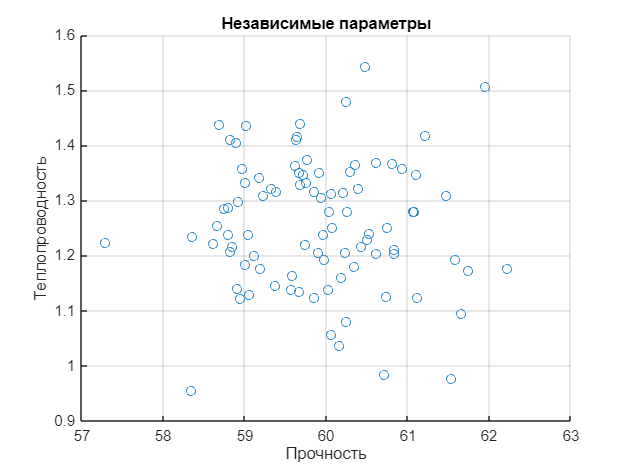

%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)

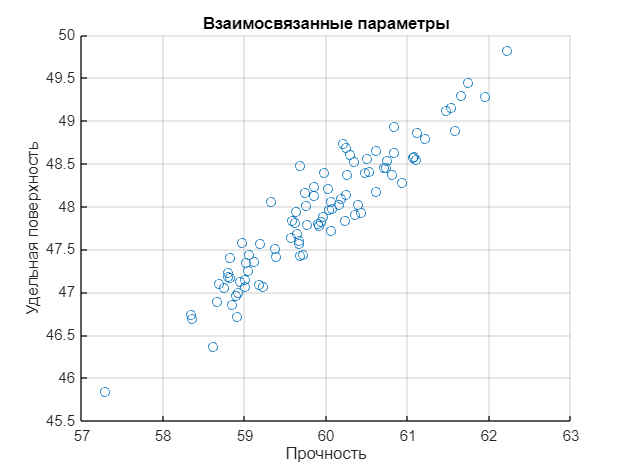

        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double

    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях

Q =     0.6170   -0.7869
   -0.7869   -0.6170


L =     0.0385
    1.3747


    if was_empty

fig13


        ax = get_next_ax();

ans =   Axes (Собственные вектора матрицы ковариации) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


    else

U =     0.7869    0.6170
    0.6170   -0.7869


S =    11.0612         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.8517         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.1792   -0.0004   -0.0776    0.1056    0.0218   -0.1170   -0.0391    0.0073   -0.1291    0.1844    0.0915   -0.0399   -0.0159    0.0298   -0.1098   -0.0259    0.2354    0.1350   -0.0380   -0.1009    0.0689    0.1504   -0.1265   -0.1299   -0.1136   -0.0130    0.1235    0.1406   -0.1292    0.0088   -0.1383    0.0020   -0.0307    0.0311   -0.0171    0.0988   -0.0209   -0.0254    0.0168    0.0446    0.0641   -0.1414   -0.1094    0.0425    0.0002   -0.0997   -0.0719    0.0385    0.1370   -0.0856
    0.0670   -0.0170   -0.2485   -0.0085    0.1309    0.1162   -0.3115    0.0318   -0.0380   -0.0156    0.0203   -0.0693    0.0113    0.0323    0.0823    0.0571    0.0615    0.0854    0.0151   -0.0686   -0.0167    0.0374   -0.0300   -0.1276   -0.1531   -0.1516    0.1685    0.1095   -0.0551   -0.0901    0.2537    0.0607    0.0149    0.0123    0.1431   -0.1442    0.1350    0.0726   -0.0108   -0.1227   -0.0859    0.0436    0.0330    0.1387    0.0464    0.0077    0.1466    0.0094    0.0851   -0

        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);

vandermonde_matrix =     1.0000   -1.5599
    1.0000    0.5637
    1.0000   -0.5920
    1.0000    0.9279
    1.0000    0.1448
    1.0000   -1.0659
    1.0000   -0.2327
    1.0000    0.0529
    1.0000   -1.1176
    1.0000    1.6212


        % end

lsqr_fit =    -0.0000
    0.6430


    end

a_lsqrt =     0.8003
    0.5996


ans =   Axes (Собственные вектора матрицы ковариации и сингулярные вектора матрицы испытаний) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


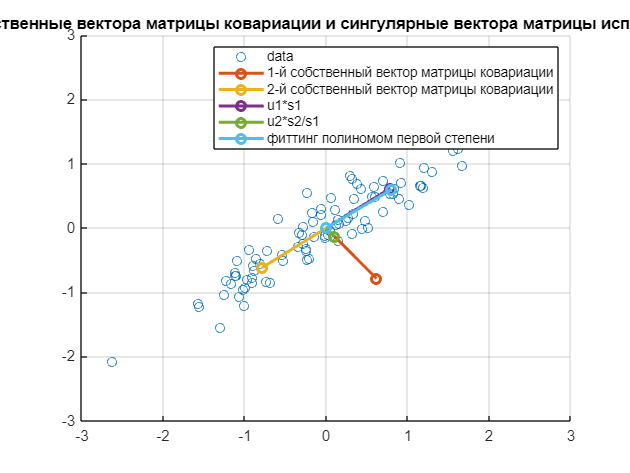

    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});

                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 

Матрица сингулярных значений матрицы испытаний (в квадрате и нормированы на (1-N)):


                for iii = 2:numel(varargin)

ans =     1.3747         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0385         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

                        [x,y,z] = make_xy(varargin{iii});

 Матрица собственных значений матрицы ковариации : 


                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');

ans =     0.0385         0
         0    1.3747


                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off

covMAT3 = 3×3
    1.0916   -0.0051    0.8389
   -0.0051    0.0076    0.0015
    0.8389    0.0015    0.6862


            end
            if isempty(names)||(numel(names)~=numel(varargin))

U = 3×3
    0.7858   -0.6030    0.1378
   -0.0018    0.2206    0.9754
    0.6185    0.7667   -0.1722


S = 3×90
   12.4868         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.5448         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.7698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


V = 90×90
   -0.0537   -0.0577   -0.0005    0.0930   -0.1385   -0.0205    0.2151    0.0160   -0.1537    0.2150   -0.0842    0.0517   -0.0331   -0.0583    0.2033   -0.0540    0.1529   -0.0655    0.0046   -0.1161   -0.0571   -0.0511   -0.1625    0.0783    0.0290    0.0022   -0.1239    0.1357    0.2756    0.1364
   -0.0471    0.0921    0.0738   -0.0041    0.0301    0.0198    0.0214   -0.2072    0.0094    0.0504    0.1124    0.2343    0.1023    0.2539   -0.0685    0.0518    0.0849   -0.1024    0.0601    0.0231    0.1226   -0.0404    0.0734    0.0094   -0.1474    0.1100    0.0417    0.0708   -0.0961   -0.0488
   -0.1837    0.0753   -0.0500   -0.1249   -0.1424   -0.0607    0.1278   -0.1466    0.0136    0.1628    0.0477    0.0519   -0.0437   -0.0601    0.0067    0.0035    0.1347   -0.0676    0.0363    0.0584    0.0780    0.0282    0.0857   -0.1925   -0.0377   -0.0085    0.0090   -0.1528    0.0878    0.1846
    0.0733    0.1268   -0.0574    0.9760   -0.0073   -0.0063   -0.0008   -0.0209    0.0

                legend(ax,string(1:numel(varargin)));

ans = -1.3878e-16

                
            else

fig11


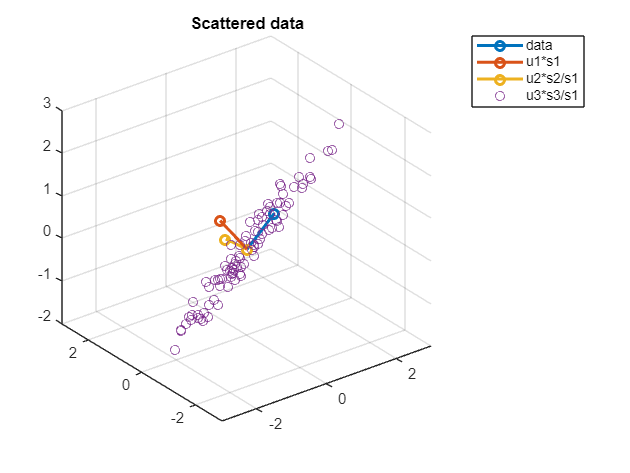

                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);

            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else

C = 5×5
    1.2861    0.2160    0.0660    0.1608    0.0737
    0.2160    1.0458   -0.0964    0.0713   -0.0456
    0.0660   -0.0964    1.1366    0.7230    0.8458
    0.1608    0.0713    0.7230    0.5497    0.5387
    0.0737   -0.0456    0.8458    0.5387    0.7022


            is_transpose = false;
        end

SIG = 5×1
    0.0258
    0.0159
    0.0102
    0.0008
    0.0004


        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end
function mem_size = mem_size_summ(varargin)
% функция считает объем несокльких переменных в памяти base workspace
    names = string(varargin);
    mem_size = 0;
    base_vars = evalin("base","whos");
    flag = arrayfun(@(X)any(strcmp(X.name,names)),base_vars);
    if ~any(flag)
        return
    end
    mem_size = sum(arrayfun(@(X)X.bytes,base_vars(flag)));
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end